#### **Project Over Basic Signal processing :**

#### **1: A Simple Train system **

**1. Transfer function**

M1=1;
M2=0.5;
k=1;
F=1;
u=0.002;
g=9.8;

num = [M2 M2*u*g 1];
den = [M1*M2 2*M1*M2*u*g M1*k+M1*M2*u*u*g*g+M2*k M1*k*u*g+M2*k*u*g];
train = tf(num, den)

train =
 
         0.5 s^2 + 0.0098 s + 1
  -------------------------------------
  0.5 s^3 + 0.0196 s^2 + 1.5 s + 0.0294
 
Continuous-time transfer function.
Model Properties


**2. State-space**

A = [0, 1, 0, 0;
-k/M1, -u*g, k/M1, 0;
0, 0, 0, 1;
k/M2, 0, -k/M2, -u*g];
B = [ 0;
1/M1;
0;
0];
C = [0, 1, 0, 0];
D = [0];
train = ss(A,B,C,D)

train =
 
  A = 
            x1       x2       x3       x4
   x1        0        1        0        0
   x2       -1  -0.0196        1        0
   x3        0        0        0        1
   x4        2        0       -2  -0.0196
 
  B = 
       u1
   x1   0
   x2   1
   x3   0
   x4   0
 
  C = 
       x1  x2  x3  x4
   y1   0   1   0   0
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.


#### **2: Modeling a Cruise Control System **

***OPEN LOOP RESPONSE***

**1. Transfer function **

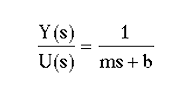 

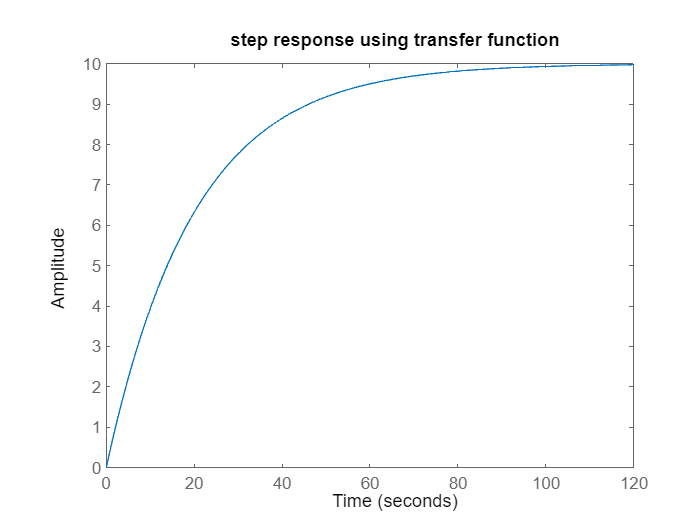

m=1000; 
b=50; 
u=500; 
num = [1]; 
den = [m b]; 
cruise = tf(num, den);
step(u*cruise)
title("step response using transfer function")

**2. State-space**

 

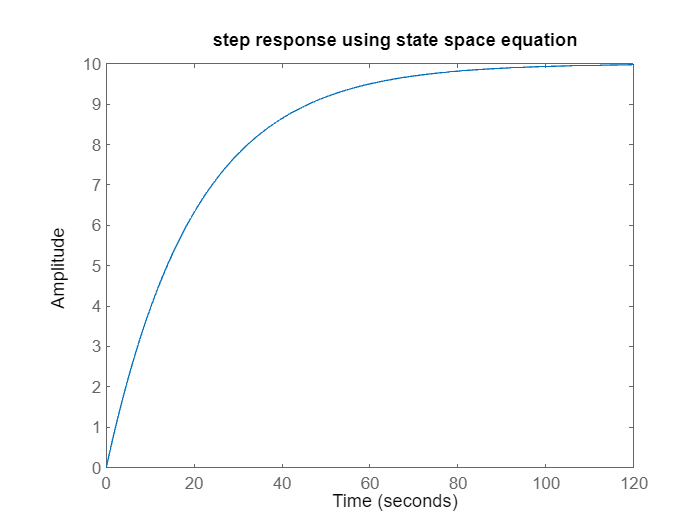

m = 1000; 
b = 50; 
u = 500; 
A = [-b/m]; 
B = [1/m]; 
C = [1];
D = 0;
cruise = ss(A,B,C,D);
step(u*cruise)
title("step response using state space equation")

#### **TASK : DC Motor Speed Modeling**

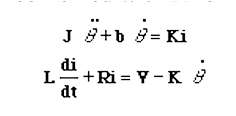

1) Express the above equations in transfer function. Where, the rotating speed is the  output and the voltage is an input. 

J = power((3.2284 + 2108043) ,-6);
b = power((3.5077 + 2108043) ,-6);
K = (0.0274 + 0.2108043);
R = 4; 
L = power((2.75 + 2108043) ,-6); 

num = K; 
den = [(J*L) ((J*R) + (L*b)) ((b*R) + K^2)]; 
motor = tf(num, den)

motor =
 
                 0.2382
  -------------------------------------
  1.298e-76 s^2 + 4.558e-38 s + 0.05674
 
Continuous-time transfer function.
Model Properties


2) Express the above equations in state-space form. 

A = [-b/J, K/J 
    -K/L, -R/L]; 
B = [0; 
     1/L]; 
C = [1, 0]; 
D = 0; 
motor_ss = ss(A, B, C, D)

motor_ss =
 
  A = 
              x1         x2
   x1         -1   2.09e+37
   x2  -2.09e+37  -3.51e+38
 
  B = 
              u1
   x1          0
   x2  8.776e+37
 
  C = 
       x1  x2
   y1   1   0
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.


3) Simulate the reference input (R) by a unit step input, then the motor speed output  should have:   

- Settling time less than 40 milliseconds  

- Overshoot less than 16% 

-  No steady-state error due to a disturbance  

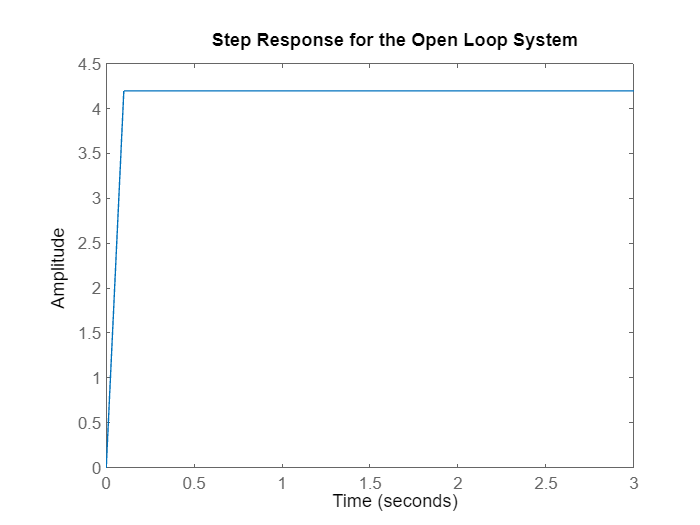

J = power((3.2284 + 2108043) ,-6);
b = power((3.5077 + 2108043) ,-6);
K = (0.0274 + 0.2108043);
R = 4; 
L = power((2.75 + 2108043) ,-6); 

num = K; 
den = [(J*L) ((J*R) + (L*b)) ((b*R) + K^2)]; 
motor = tf(num, den);

step(motor,0:0.1:3); 
title('Step Response for the Open Loop System'); 

**Example-4: A simple mass, spring, and damper problem. **

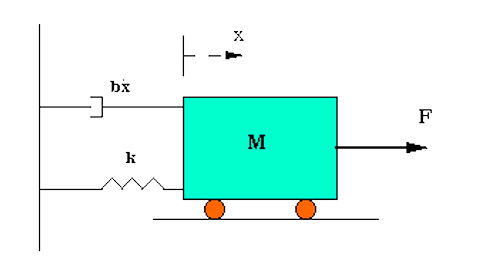

The modeling equation of this system is  

The transfer function is

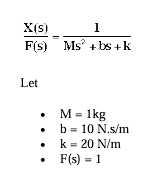

***Open loop step response***

M = 1;
b = 10;
k = 20;

num = 1; 
den = [M b k]; 
plant = tf(num, den)

plant =
 
         1
  ---------------
  s^2 + 10 s + 20
 
Continuous-time transfer function.
Model Properties


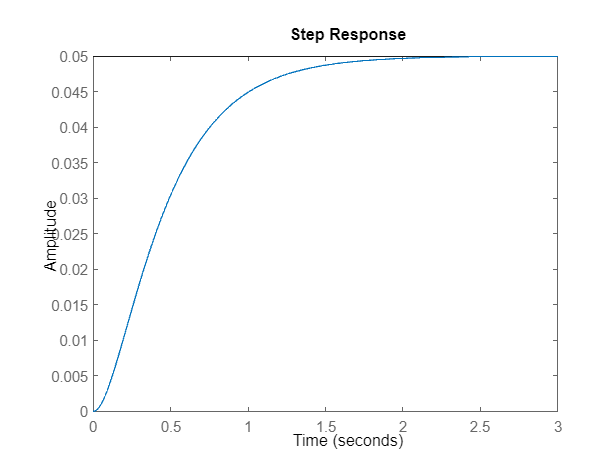

step(plant)

#### ***Closed loop step response***

**The proportional controller (Kp) r**educes the rise  time, increases the overshoot, and reduces the steady-state error. The closed-loop transfer  function of the above system with a proportional controller is: 

For fast rise time lets use Proportional Controller(Kp) 

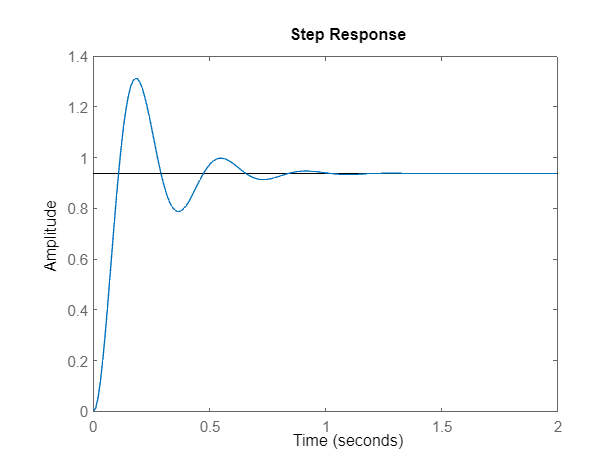

Kp = 300; 
contr = Kp; 
sys_cl = feedback(contr*plant,1); 
t=0:0.01:2; 
step(sys_cl,t) 

Lets increase Kp

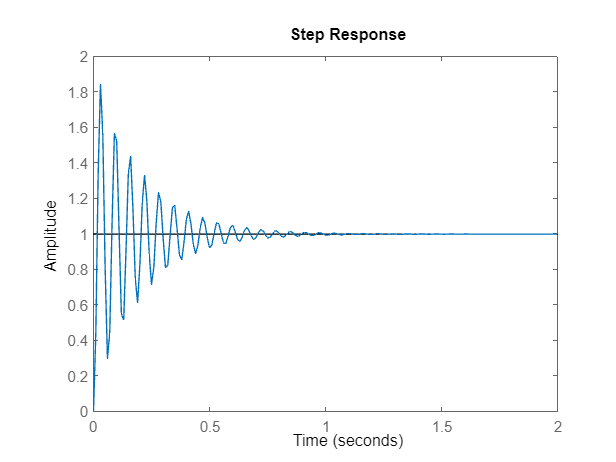

Kp = 10000; 
contr = Kp; 
sys_cl = feedback(contr*plant,1); 
t=0:0.01:2; 
step(sys_cl,t) 

Lets decrease Kp

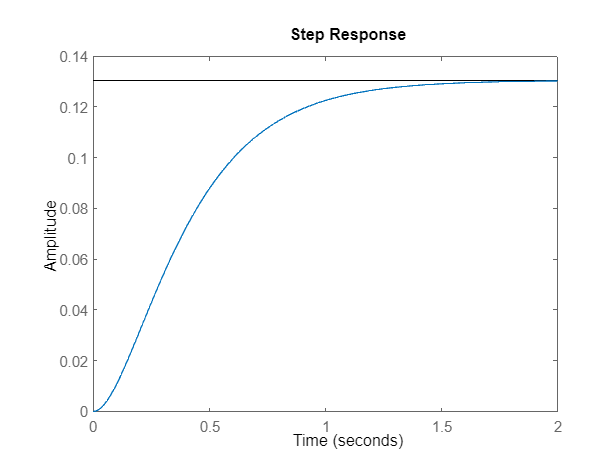

Kp = 3; 
contr = Kp; 
sys_cl = feedback(contr*plant,1); 
t=0:0.01:2; 
step(sys_cl,t) 

Here it can be seen, by increaseing Kp the rise time increases and vice versa,On both case no change is seen in settling time, but steady state error occured when Kp is decreased..

**The Derivative  controller (Kd)** reduces both the overshoot and the settling time. The closed-loop transfer  function of the given system with a PD controller is: 

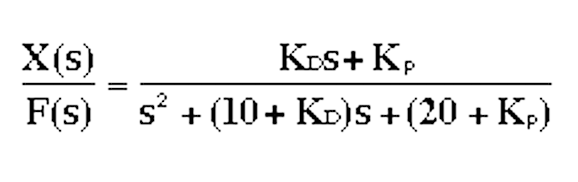

 Lets use Proportional Derivative Controller

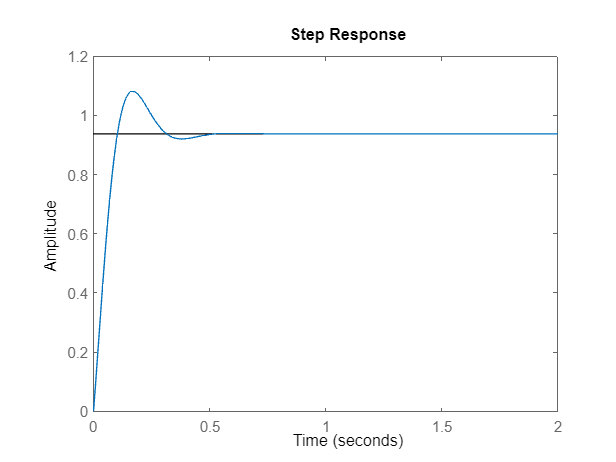

Kp = 300; 
Kd = 10; 
contr = tf([Kd Kp],1);  
sys_cl = feedback(contr*plant,1); 
t=0:0.01:2; 
step(sys_cl,t) 

Lets decrease Kp and Increase Kd

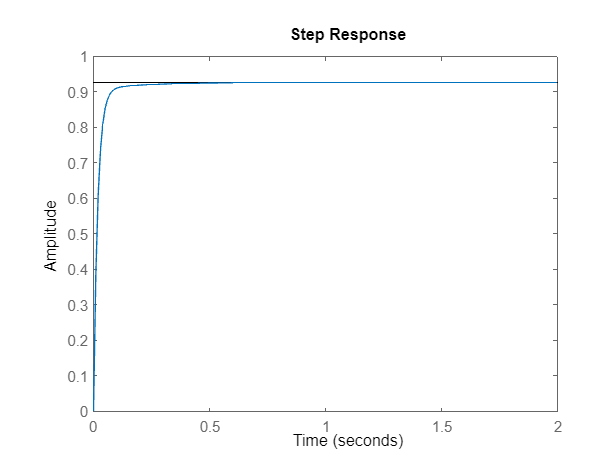

Kp = 250; 
Kd = 50; 
contr = tf([Kd Kp],1);  
sys_cl = feedback(contr*plant,1); 
t=0:0.01:2; 
step(sys_cl,t)

Here, increased Kd resulted in lower settling time and overshoot.

Lets decrease Kp and Increase Kd more

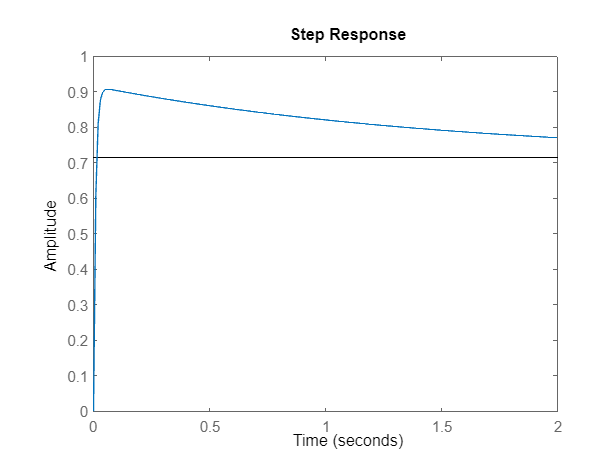

Kp = 50; 
Kd = 100; 
contr = tf([Kd Kp],1);  
sys_cl = feedback(contr*plant,1); 
t = 0:0.01:2; 
step(sys_cl,t)

Due to lower Kp steady state error increased.

**An integral controller (Ki)** decreases the rise time, increases both the overshoot and the  settling time, and eliminates the steady-state error. For the given system, the closed-loop  transfer function with a Proportional Integral control is: 

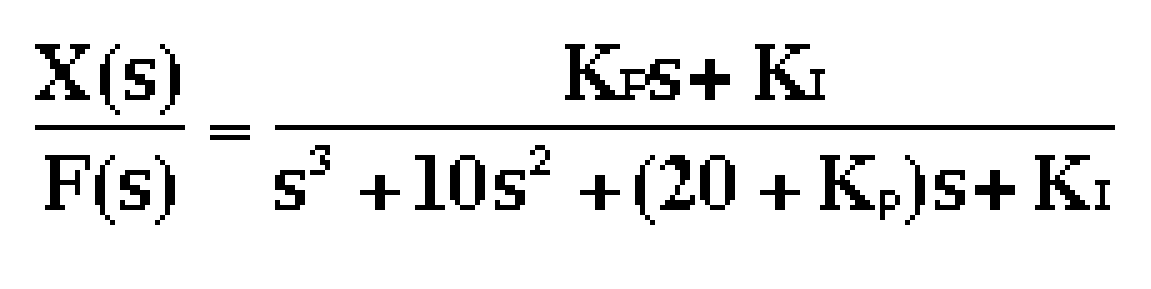

 Lets use Proportional Integral Controller

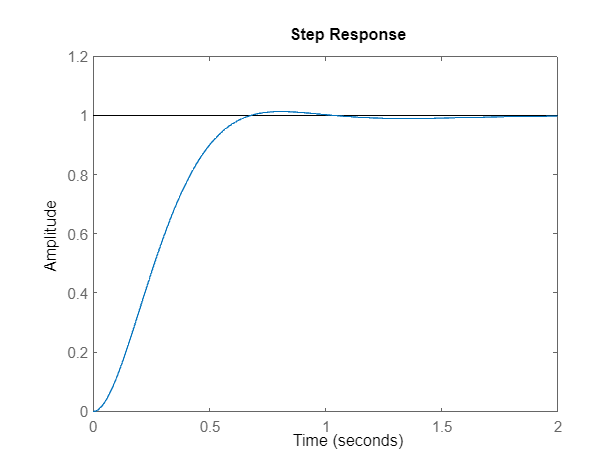

Kp = 30; 
Ki = 70; 
contr = tf([Kp Ki],[1 0]);  
sys_cl = feedback(contr*plant,1); 
t = 0:0.01:2; 
step(sys_cl,t) 

Lets increase Ki and Kp

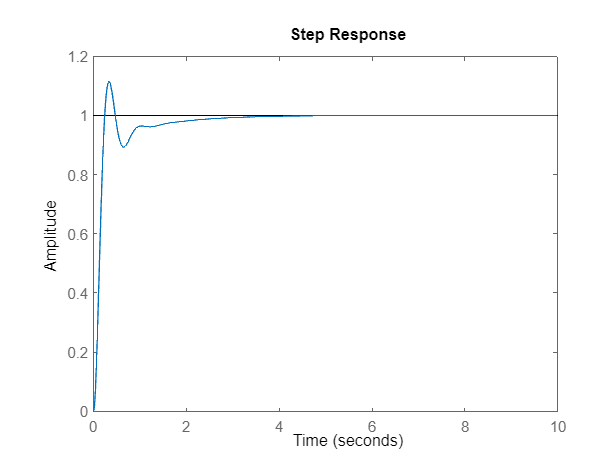

Kp = 100; 
Ki = 100; 
contr = tf([Kp Ki],[1 0]);  
sys_cl = feedback(contr*plant,1); 
t = 0:0.01:10; 
step(sys_cl,t) 

Here, increase in in Kp and Ki caused overshoot.

Lets decrease Ki and Kp

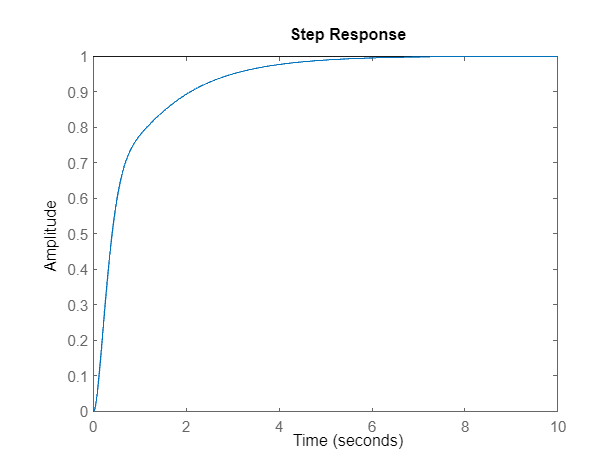

Kp = 20; 
Ki = 25; 
contr = tf([Kp Ki],[1 0]);  
sys_cl = feedback(contr*plant,1); 
t = 0:0.01:10; 
step(sys_cl,t) 

Here, decrease in  Kp and Ki caused increased rise time.

#### **Proportional-Integral-Derivative control **

PID uses pros of all three controller for lower settling time & rise time, elimnating overshoot and steady state error. The closed-loop transfer function of the given  system with a PID controller is:  

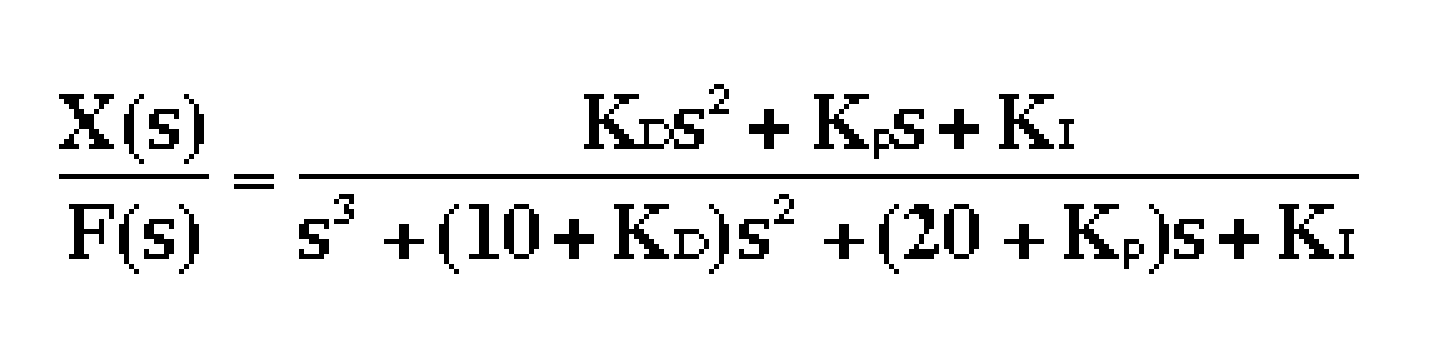

Lets use PID control for the given system

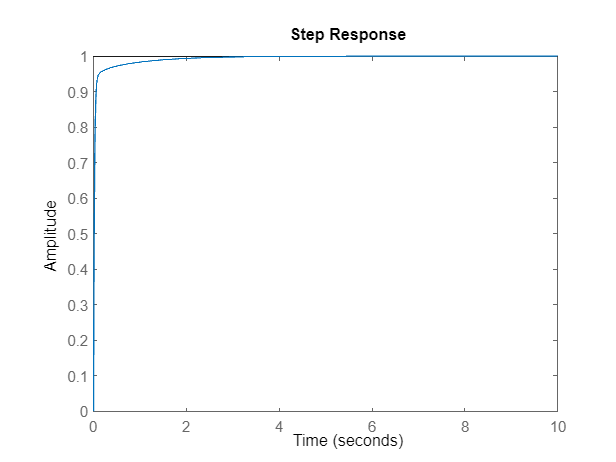

Kp = 350; 
Ki = 300; 
Kd = 50; 
contr = tf([Kd Kp Ki],[1 0]);  
sys_cl = feedback(contr*plant,1); 
t = 0:0.01:10; 
step(sys_cl,t) 

 Here , a perfect combination of Kp Ki and Kd value resulted in a efficient control system for the given system.

### **Example- 5: Modeling a Cruise Control System Using PID control **

The transfer function for this cruise control problem is the following 

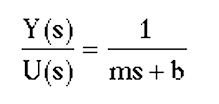

The design criteria for this problem are:  Rise time < 5 sec  Overshoot < 10%  Steady state error < 2% 

m = 1000; 
b = 50; 
u = 10; 
num = [1]; 
den = [m b]; 
cruise = tf(num,den)

cruise =
 
       1
  -----------
  1000 s + 50
 
Continuous-time transfer function.
Model Properties


**For Proportional control Transfer function is**

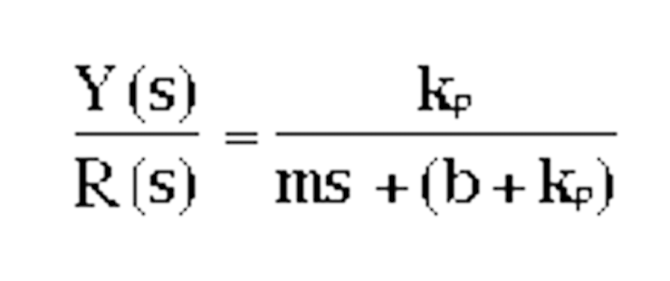

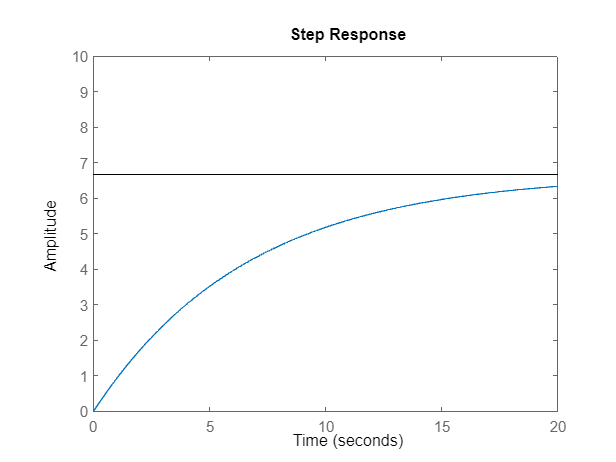

Kp = 100;
sys_cl = feedback(Kp*cruise,1); 
t = 0:0.1:20; 
step(u*sys_cl,t) 
axis([0 20 0 10]) 

Increasing Kp to 10000 for lowering rise time

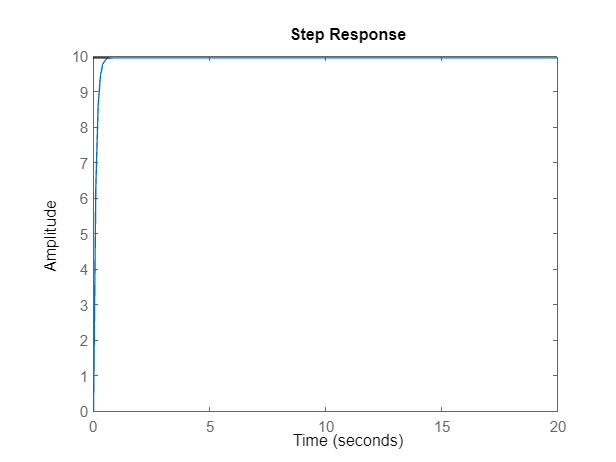

Kp = 10000;
sys_cl = feedback(Kp*cruise,1); 
t = 0:0.1:20; 
step(u*sys_cl,t) 
axis([0 20 0 10])

**The closed-loop transfer function of this cruise control system with a PI controller is:  **

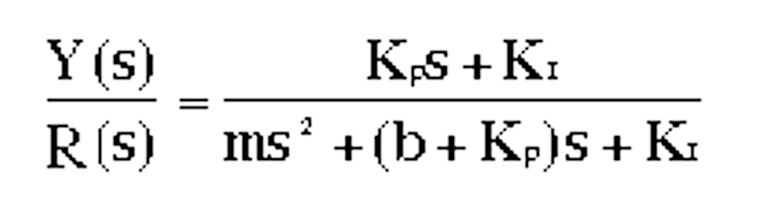

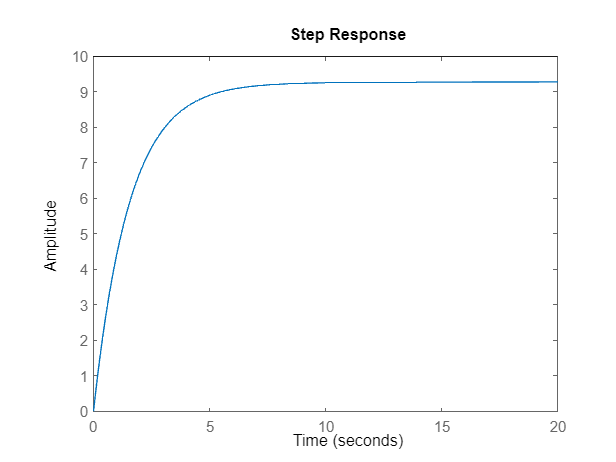

Kp = 600; 
Ki = 1; 
contr = tf([Kp Ki],[1 0]);  
sys_cl = feedback(contr*cruise,1); 
t = 0:0.1:20; 
step(u*sys_cl,t) 
axis([0 20 0 10])

When Kp equal 800 and Ki equal 40, the step response will look like the following: 

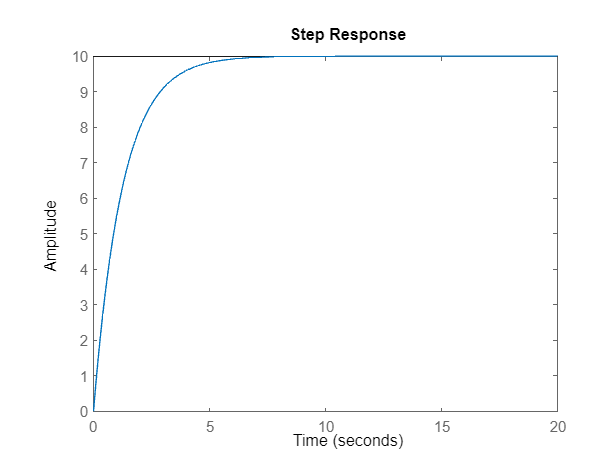

Kp = 800; 
Ki = 40; 
contr = tf([Kp Ki],[1 0]);  
sys_cl = feedback(contr*cruise,1); 
t = 0:0.1:20; 
step(u*sys_cl,t) 
axis([0 20 0 10])

**The closed-loop transfer function for this cruise control system with a  PID controller is**

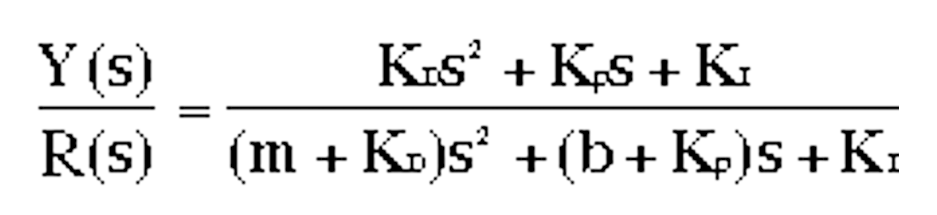

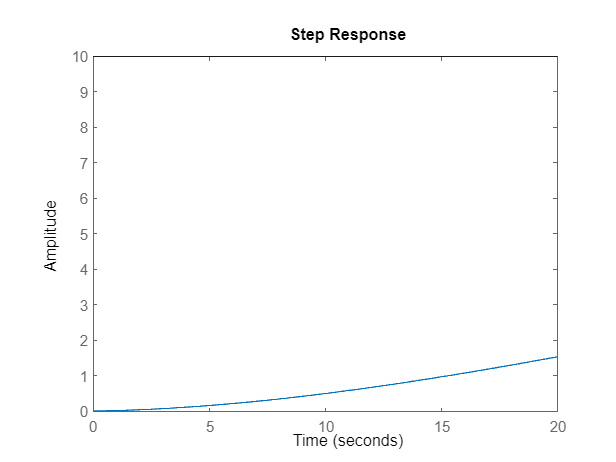

Kp = 1; 
Ki = 1; 
Kd = 1; 
contr = tf([Kd Kp Ki],[1 0]);  
sys_cl = feedback(contr*cruise,1); 
t = 0:0.1:20; 
step(u*sys_cl,t) 
axis ([0 20 0 10])

Lets adjust Kp for making rise time < 5s

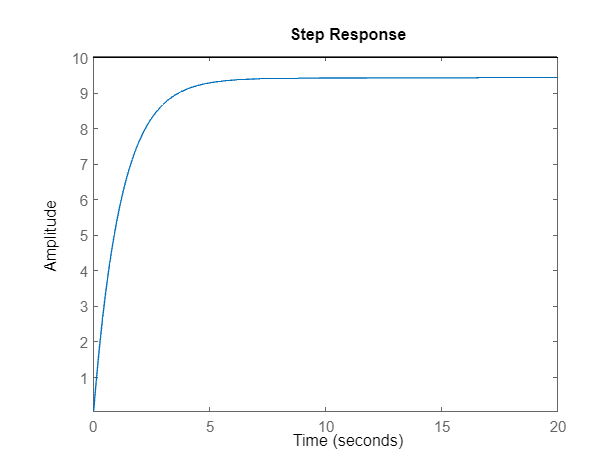

Kp = 800; 
Ki = 1; 
Kd = 1; 
contr = tf([Kd Kp Ki],[1 0]);  
sys_cl = feedback(contr*cruise,1); 
t = 0:0.1:20; 
step(u*sys_cl,t) 
axis ([0 20 0 10])

Now, adjusting Ki for eliminating steady state error 

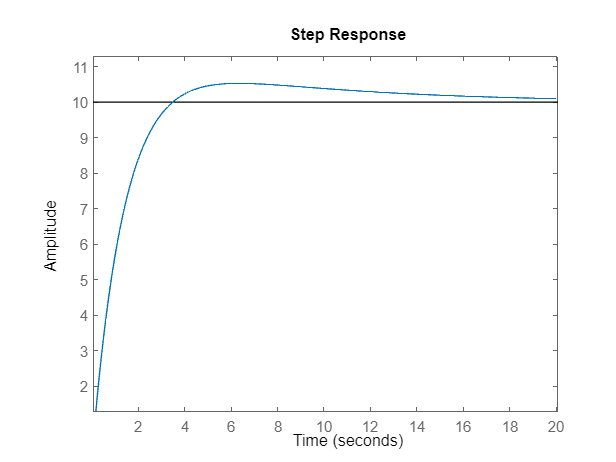

Kp = 800; 
Ki = 100; 
Kd = 1; 
contr = tf([Kd Kp Ki],[1 0]);  
sys_cl = feedback(contr*cruise,1); 
t = 0:0.1:20; 
step(u*sys_cl,t) 
axis ([0 20 0 10])

Last but no least, adjusted Kd for lowering overshoot to less then 10%

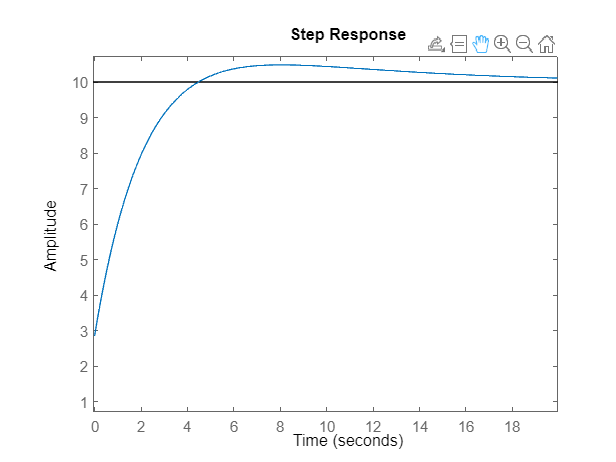

Kp = 800; 
Ki = 100; 
Kd = 400;
contr = tf([Kd Kp Ki],[1 0]);  
sys_cl = feedback(contr*cruise,1); 
t = 0:0.1:20; 
step(u*sys_cl,t) 
axis ([0 20 0 10])

This is the control system for the cruise according to criteria.

### **TASK : DC Motor Speed Modeling using PID control**

The dynamic equations and the open-loop transfer function of the DC Motor are: 

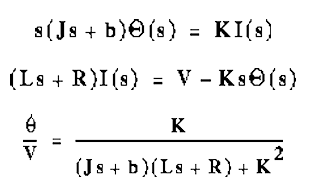

With a 1 rad/sec step input, the design criteria are:  

- Settling time less than 2 seconds  

- Overshoot less than 5%  

- Steady-stage error less than 1% 

Lets use a combination of Kp Ki Kd for full filling requirments

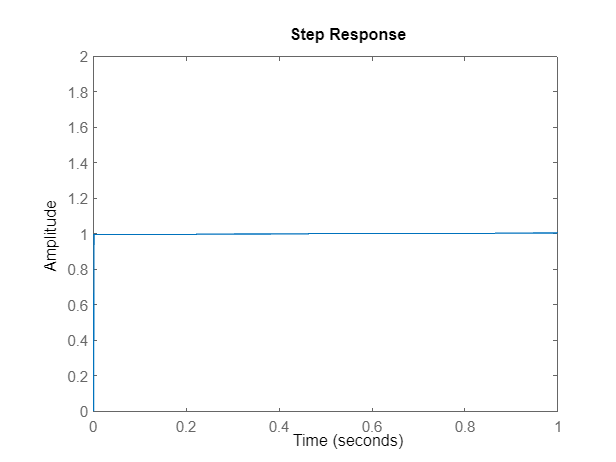

J = power((0.01 + 2108036) ,-6);
b = power((0.1 + 2108036) ,-6);
K = (0.01 + 0.2108036);
R = 1; 
L = power((0.5 + 2108036) ,-6); 
u = 1;

num = K; 
den = [(J*L) ((J*R) + (L*b)) ((b*R) + K^2)]; 
motor = tf(num, den);

Kp = 50; 
Ki = 100; 
Kd = 0;
contr = tf([Kd Kp Ki],[1 0]);  
sys_cl = feedback(contr*motor,1); 

t = 0:0.001:2; 
step(u*sys_cl,t) 
axis ([0 1 0 2])

This the PID control  fullfilling all the criteria.

### **Discussion:**

- In this experiment, open loop and closed loop control systems step reponse in different conditions were plotted.

- In open loop control system, no feed back is required, which results in low effiecient control sytem.

- For closed loop control system , Proportional (Kp), Integral(Ki) , Derivative(Kd) control was used. Where increasing Kp leads to lower rise time, increasing Ki leads to elimination of stead state error, increasing Kd leads to lower settling time & overdshoot.